

% % If testing the function : uncomment the code inside the "=" symbols , otherwise
% % comment it to call the filter inside some other executable

% % this example follows the trajectory of a falling meteor and is taken
% % from ch.5 of Beyond Kalman Filters


% ================================================================
% ================================================================
% ================================================================


clear all
clc

N = 300;

x = zeros(12,N);
x(:,1) = [0 ; 0; 2 ; 0 ; 0 ; 0; 1 ; 0 ; 0 ; 0; 0.5 ; 0];

dT = 0.01;

tau_x = 14.97;
tau_y = 14.97;
tau_z = 3.175;

beta_x = 1/tau_x;
beta_y = 1/tau_y;
beta_z = 1/tau_z;


Fx = [0 1 0 0 ; 0 0 -1 -1 ; 0 0 0 0 ; 0 0 0 -beta_x ];
Fy = [0 1 0 0 ; 0 0 -1 -1 ; 0 0 0 0 ; 0 0 0 -beta_y ];
Fz = [0 1 0 0 ; 0 0 -1 -1 ; 0 0 0 0 ; 0 0 0 -beta_z ];

F = blkdiag(Fx,Fy,Fz)

F =          0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0   -1.0000   -1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0   -0.0668         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0   -1.0000   -1.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   -0.0668         0         0         0         0
         0         0        



H = [1 0 0 0 0 0 0 0 0 0 0 0;
     0 1 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0 0;];

u = zeros(3,N);
B = [0 0 0 ;
    1 0 0 ;
    0 0 0 ;
    0 0 0 ;
    0 0 0 ;
    0 1 0 ;
    0 0 0 ;
    0 0 0 ;
    0 0 0 ;
    0 0 1 ;
    0 0 0 ;
    0 0 0 ;]

B =      0     0     0
     1     0     0
     0     0     0
     0     0     0
     0     0     0
     0     1     0
     0     0     0
     0     0     0
     0     0     0
     0     0     1



Fd = eye(12) + F*dT;
Bd = Fd*B*dT;

P = zeros(12,12, N);

z = zeros(6,N);
R = eye(6);
Rd = R/dT;

N_x = 4.9e-4;
K_x = 3.0e-5;
Q_gm_x = 9.2e-5;


N_y = 4.9e-4;
K_y = 3.0e-5;
Q_gm_y = 9.2e-5;


N_z = 5.8e-4;
K_z = 4.0e-5;
Q_gm_z = 5.9e-4;

Qx = [0 0 0 0;
      0 N_x*N_x 0 0;
      0 0 K_x*K_x 0;
      0 0 0 Q_gm_x];

Qy = [0 0 0 0;
      0 N_y*N_y 0 0;
      0 0 K_y*K_y 0;
      0 0 0 Q_gm_y];

Qz = [0 0 0 0;
      0 N_z*N_z 0 0;
      0 0 K_z*K_z 0;
      0 0 0 Q_gm_z];

Q = blkdiag(Qx,Qy,Qz);

Qd = dT*Fd*Q*Fd';

P(:,:,1) =  eye(12) ;

for i = 1 : N-1
    u(:,i) = rand(3,1);
    z(:,i) = H*x(:,i) + mvnrnd(zeros(6,1) , R)';
    x_dot = F*x(:,i) + B*u(:,i) +  mvnrnd(zeros(12,1) , Q)';
    x(:,i+1) = dT*x_dot + x(:,i);
end

x_hat = zeros(12,N);
x_hat(:,1) = 2*rand(12,1);
for i = 1 : N-1
   [ x_hat(:,i+1) , P(:,:,i+1) ]= mykf( Fd , H , x_hat(:,i) , P(:,:,i) , u(:,i) , Bd , Qd , z(:,i) , Rd );
end



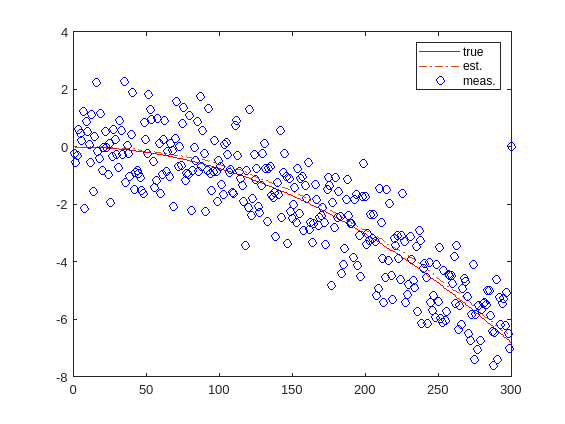


figure
plot(x(1,:),"red")
hold on
plot(x_hat(1,:), "LineStyle","-.")
scatter([1:1:N], z(1,:), "blue")
legend("true","est.","meas.")

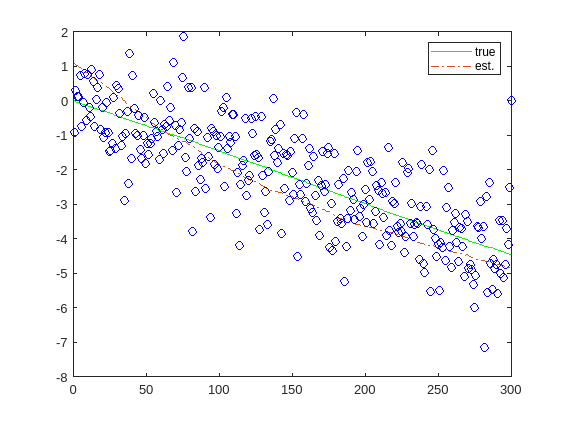



figure
plot(x(2,:),"green")
hold on
plot(x_hat(2,:), "LineStyle","-.")
scatter([1:1:N], z(2,:), "blue")
legend("true","est.")

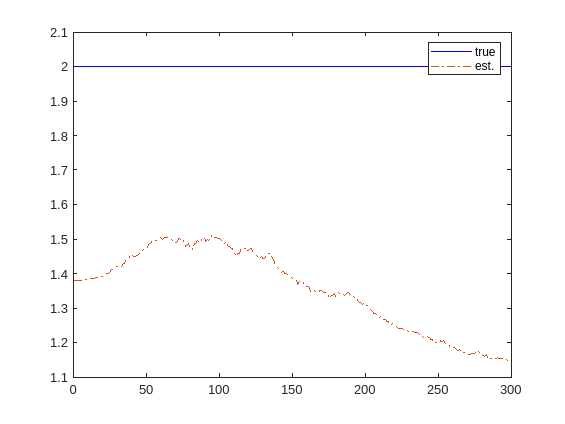


figure
plot(x(3,:),"blue")
hold on
plot(x_hat(3,:), "LineStyle","-.")
legend("true","est.")

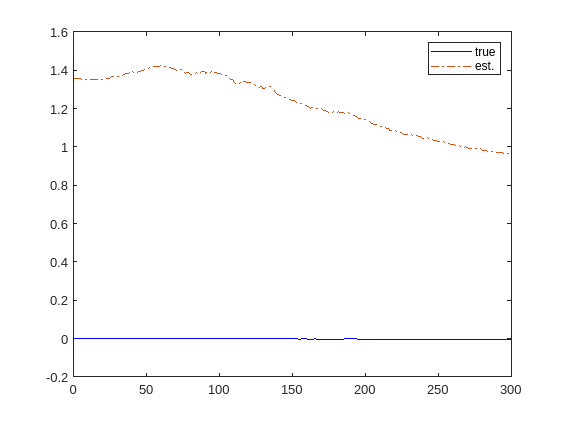


figure
plot(x(4,:),"blue")
hold on
plot(x_hat(4,:), "LineStyle","-.")
legend("true","est.")


% ================================================================
% ================================================================
% ================================================================


% % % % % % 


function [ x_out , P_out ] = mykf( F_in , H_in , x_in , P_in , u_in , B_in , Q_in , z_in , R_in )

sizes_P = size(P_in);
I = eye(sizes_P(1));

% Predict
x_pred = F_in*x_in + B_in*u_in ;
P_pred = F_in*P_in*F_in' + Q_in;
y_pred = H_in*x_pred;

 

% Update
K = P_pred*(H_in')*inv(H_in*P_pred*(H_in') + R_in);
x_out = x_pred + K*(z_in - y_pred);
P_out = (I - K*H_in)*P_pred*((I - K*H_in)') + K*R_in*(K');

end